# Práctica 2

## 3. Solucionar de manera numérica ecuaciones diferenciales.

Se lanza un proyectil hacia arriba desde la superficie de la Tierra con una velocidad inicial de 1500 m/s. Se acepta que la única fuerza que actúa sobre el objeto es la fuerza debida a la gravedad hacia abajo. En estas condiciones, se usa un balance de fuerzas para obtener:


$$\frac{\mathrm{d}}{\mathrm{d}t}v=-g\frac{R^2 }{{\left(R+x\right)}^2 }$$


donde $v$ es la velocidad hacia arriba (m/s), $x$ es la altitud (m) medida hacia arriba a partir de la superficie terrestre y *R* es el radio de la Tierra. 

Grafica (solo) la altura $x$ del proyectil en los primeros 250s de vuelo. Utiliza el método rk4 y h=0.1.

R = 6.37e6;
g = 9.81;

%   x' = v
%   v' = x'' = -g * (R^2/(R+x)^2)

f = @(t,xv) [xv(2); -g*(R^2/(R+xv(1))^2)];
y0 = [0;1500];


t0 = 0;
tf = 250;
h = 0.1;

[t,xv] = TerPar_RK4(f,t0,y0,h,tf);%TerPar_RK4(f,t0,y0,h,tf)
plot(t,xv(1,:))
title('Altura (x) del proyectil')
xlabel('Tiempo (s)')
ylabel('Altura (m)')
hold on

Calcula la máxima altura que alcanza el proyectil (usando los valores de *x* calculados antes) y en cuánto tiempo la alcanza?

[maxAlt,idx] = max(xv(1,:));

plot(t(idx),xv(1,idx),'or')
hold off

%   La altura máxima alcanzada es
maxAlt
%   Y el tiempo en que se alcanza es
t(idx)

## 4. Familiarizarse con el modelado matemático de sistemas físicos.

Un péndulo amortiguado pierde energía y, a partir de cualquier condición inicial, termina en la posición vertical de reposo. La fuerza amortiguamiento, friction, se modela frecuentemente como proporcional y en el sentido opuesto a la velocidad. La ecuación del péndulo queda entonces como

 
$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\theta +\mu \frac{d}{\mathrm{d}t}\theta +\frac{g}{l}\;\theta =0$$


donde $\mu >0$ es el coeficiente de amortiguamiento.

Grafica (solo) la posición $\theta$ del péndulo en función del tiempo durante 20s. La posición inicial es $\theta_0 =\frac{\pi }{8}$ y la velocidad inicial es cero.

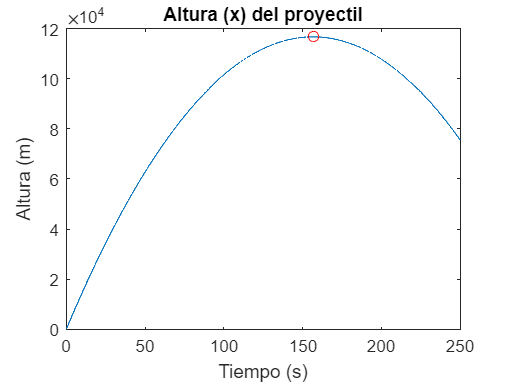

%   y'' + mu*y' + (g/l)*y = 0
%   y' = z
%   z' = y'' =-(g/l)*y -mu*z

g = 9.81;
l = 1;
d = 0.25;

maxAlt = 1.1678e+05

t0 = 0;
tf = 20;

ans = 156.7000

h = 0.1;


M = [0 1;-g/l -d];
yz0 = [pi/8;0];
f = @(t,yz) M*yz;

[t,yz] = TerPar_RK4(f,t0,yz0,h,tf);%TerPar_RK4(f,t0,y0,h,tf)
plot(t,yz)


hold on
plot(3.1321,-0.2:0.01:0.2,'-')
hold off

A partir de los valores propios de la matriz que describe el sistema, determina ¿cuál es el período (en *s*) de la parte oscilatoria de la respuesta? 

V = eig(M)
p = abs(V(1))

¿Cuál es la constante de decaimiento (en $s^{-1}$) de la envolvente exponencial?

1/p

## 5. Entender el funcionamiento de diversos métodos numéricos.

Resuelve la ecuación 


$$\frac{{\mathrm{d}}^3 }{\mathrm{d}t^3 }x+x=0$$


con las condiciones iniciales $x^{\prime \prime } \left(0\right)=0,{\;x}^{\prime } \left(0\right)=1,\;x\left(0\right)=0$.

Grafica x(t) en el intervalo [0 , 10] .

Solución simbólica


$$x''' + x = 0
\\
x' = y
\\
y' = x'' = z
\\
z' = x''' = -x$$


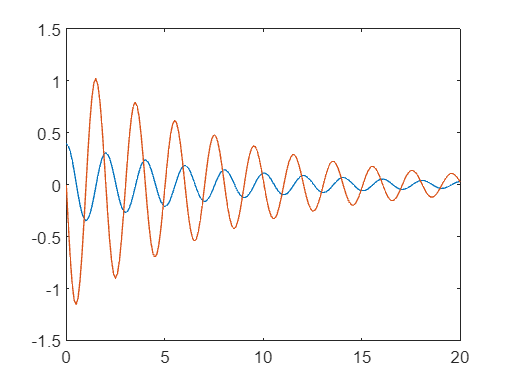

syms x(t)
eqn = diff(x,3) == -x
d2 = diff(x,2)
d = diff(x)
cond = x(0) == 0;
cond2 = d(0) == 1;
cond3 = d2(0) == 0;
x = dsolve(eqn,cond,cond2,cond3);

fplot(x,[0 10])
xlabel('t'); ylabel('x')

Solución numérica

M = [0 1 0;0 0 1;-1 0 0];
yz0 = [0;1;0];

V =   -0.1250 + 3.1296i
  -0.1250 - 3.1296i


f = @(t,yz) M*yz;

p = 3.1321

t0 = 0;
tf = 10;

ans = 0.3193

h = 0.001;%Ojo euller funciona MUCHO mejor con una h pequeña. 

[t,y] = TerPar_odeEuler(f,t0,yz0,h,tf);%TerPar_odeEuler(f, to, yo, h, tf)
plot(t,y(1,:))
%plot(t,y)
%legend("x", "x'", "x''")
xlabel('t'); ylabel('x')


## A partir de aquí probablemente no venga...

## 1. Utilizar un lenguaje de programación matricial de manera eficiente.

1.1 En los métodos multipasos para resolver ecuaciones diferenciales ordinarias se utilizan los últimos* k* valores calculados de la función para determinar el valor de la variable en el siguiente punto. Para no guardar todos los valores calculados de la función, puede usarse una cola de tamaño k.  

De manera eficiente agrega 60 a la siguiente cola (k=4). Tu solución no debe depender del contenido de la cola en el ejemplo.

cola = [40,45,50,55];
% la cola debe quedar [45,50,55,60];

$$eqn(t) = \frac{\partial^{3}}{\partial t^{3}}x\left(t\right)=-x\left(t\right)$$

cola = [cola(2:end) 60]

$$d2(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

1.2 A partir de la matriz A 

A = magic(5)

$$d(t) = \frac{\partial }{\partial t}x\left(t\right)$$

calcula de la manera más compacta posible:

a) La suma del último renglón de la matriz 

sum(A(end,:))

b) La mediana de A 

med = median(A,"all")

c) Cuántos elementos de A son menores a la mediana

length(A(A<med))

## 2. Identificar los errores numéricos de las soluciones computacionales.

2.1 La serie infinita


$$f\left(n\right)=\sum_{i=1}^n \frac{1}{i^4 }$$


converge a $\frac{\pi^4 }{90}$ conforme $n$ tiende a infinito. Escribe un programa de precisión sencilla para calcular $f\left(n\right)$ para $n=10000$, calculando primero la suma desde $i=1$ hasta 10000 y después en sentido inverso (desde $i=10000$ hasta 1). En lo dos casos, calcula el error absoluto. 

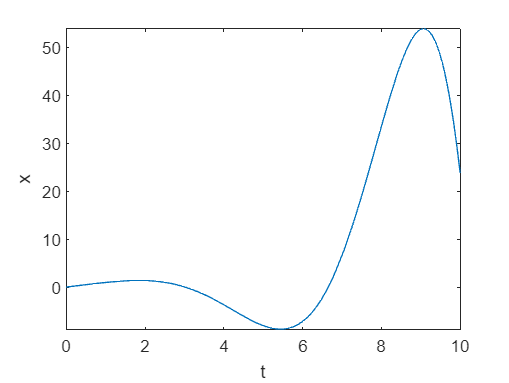

 real = single(pi^4/90)
 suma = single(0)
 n = 10000;
 

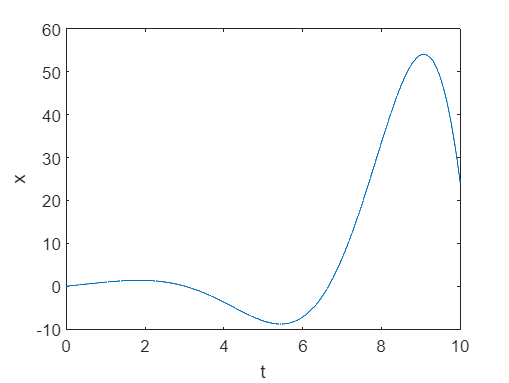

 format long
 %  Suma ascendente
 i = 1:n;
 s = sum(1./i.^4);
 suma = s + suma
 
 err = real - suma
 %  Suma descendente
 suma = single(0);
 
 i = n:-1:1;
 s = sum(1./i.^4);
 suma = s + suma

 err = real - suma
 
 format short

Explica claramente por qué la suma ascendente tiene un error y la descendente no.

2.2 Determina el número de términos necesarios para aproximar $\cos \left(0\ldotp 3\pi \right)\;$ a 8 decimales con el uso de la serie de Maclaurin.

$\cos \;x=1-\frac{x^2 }{2!}$+$\frac{x^4 }{4!}$-$\frac{x^6 }{6!}$+$\frac{x^8 }{8!}-\cdots$

format long
n = 10; %   El valor de la potencia
i = 0:2:n
real = round(cos(0.3*pi),8)


x = 0.3*pi;
pM = @(x,n) x.^n./factorial(n);
s = pM(x,i);
j = [1 -1 1 -1 1 -1];
s = s.*j;
val = round(sum(s),8)

error = real - val

format short

%   Se necesitan 6 terminos de la serie de McLaurin 
%   para tener una precisión de 8 decimales